A = [-2, 0, -4, 2;
    0, 2, -2 ,4;
    -4, -2, 2, 0;
    2, 4, 0, 2];
B = [8; 6; 4; 2];
C = [1, 1, 1, 1;
    1, 1, 1, 1];

x0 = [1; 2; 3; 4];
x1 = [0; 8; 1; 6];

a = 2;
a1 = 5

a1 = 5

warning off;
cvx_begin sdp

variable P(4,4)
variable Y1(1,4)
variable Q(4,4)
variable Y2(4,2)

P > 0.0001*eye(4);
P*A'+ A*P + 2*a*P +Y1'*B' +B*Y1 <= 0;

Q > 0.0001*eye(4);
A'*Q+ Q*A + 2*a1*Q +C'*Y2' +Y2*C <= 0;
cvx_end

 
Calling SDPT3 4.0: 56 variables, 20 equality constraints
------------------------------------------------------------

 num. of constraints = 20
 dim. of sdp    var  = 16,   num. of sdp  blk  =  4
 dim. of free   var  = 16 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|8.0e+02|3.4e+02|6.0e+04| 0.000000e+00  0.000000e+00| 0:0:00| chol  1  1 
 1|0.835|0.871|1.3e+02|4.4e+01|2.8e+03| 0.000000e+00  2.914715e-02| 0:0:00| chol  1  1 
 2|0.921|0.856|1.0e+01|6.4e+00|2.3e+02| 0.000000e+00  3.064153e-02| 0:0:00| chol  1  1 
 3|0.890|0.851|1.1e+00|9.5e-01|2.8e+01| 0.000000e+00  2.834735e-02| 0:0:00|


Kl = Y1*pinv(P)

Kl =   -30.5355   53.6216  -13.9800   50.0803
         0         0         0         0


M1 = A + B*Kl;
Me1 = eig(M1)

Me1 =   -5.3170 + 4.5728i
  -5.3170 - 4.5728i
  -3.2366 + 1.2782i
  -3.2366 - 1.2782i



L2 = pinv(Q)*Y2

L2 =   449.1542  449.1541
 -156.8120 -156.8120
 -383.3033 -383.3033
   73.9200   73.9200


M2 = A + L2*C;
Me2 = eig(M2)

Me2 =  -10.8797 +19.4607i
 -10.8797 -19.4607i
  -6.1615 + 2.6602i
  -6.1615 - 2.6602i


Построение графиков

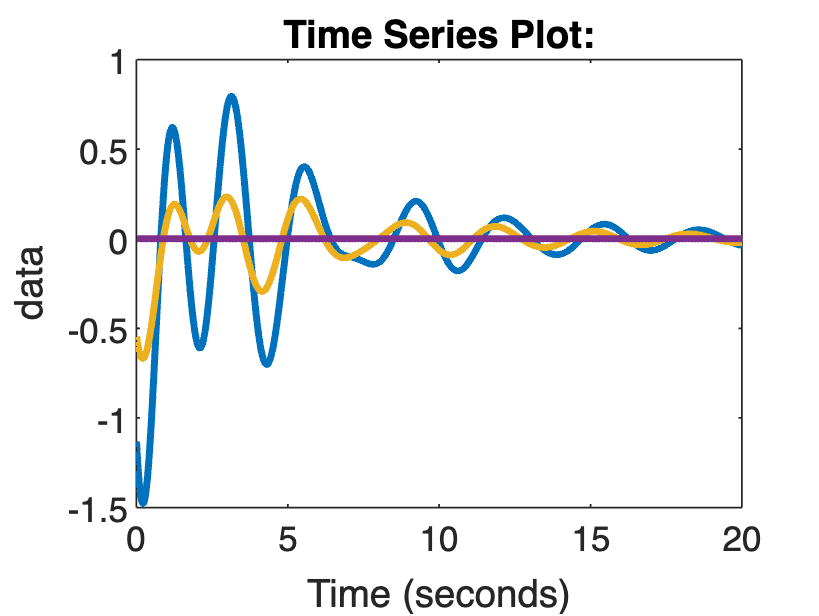

plot(out.u, 'LineWidth', 2);
hold on;

plot(out.u1, 'LineWidth', 2, 'LineStyle','--');

Unrecognized field name "u1".

hold on;
plot(out.u2, 'LineWidth', 2, 'LineStyle',':');
hold on;
title('u(t)','Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
legend("$u_{\alpha_{1}}$(t)","$u_{\alpha_{2}}$(t)", "$u_{\alpha_{3}}$(t)", 'Interpreter', 'latex', 'FontSize', 15);
grid on;
hold off;

plot(out.e.Time, out.e.Data(:,1), 'LineWidth', 2);
hold on;
plot(out.e1.Time,out.e1.Data(:,1), 'LineWidth', 2, 'LineStyle','--');
hold on;
plot(out.e2.Time,out.e2.Data(:,1), 'LineWidth', 2, 'LineStyle',':');
title('$e_{1}(t)$','Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
legend("$e_{\alpha_{1}}$(t)","$e_{\alpha_{2}}$(t)", "$e_{\alpha_{3}}$(t)", 'Interpreter', 'latex', 'FontSize', 15);
grid on;
hold off;

plot(out.e.Time, out.e.Data(:,2), 'LineWidth', 2);
hold on;
plot(out.e1.Time,out.e1.Data(:,2), 'LineWidth', 2, 'LineStyle','--');
hold on;
plot(out.e2.Time,out.e2.Data(:,2), 'LineWidth', 2, 'LineStyle',':');
title('$e_{2}(t)$','Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
legend("$e_{\alpha_{1}}$(t)","$e_{\alpha_{2}}$(t)", "$e_{\alpha_{3}}$(t)", 'Interpreter', 'latex', 'FontSize', 15);
grid on;
hold off;

plot(out.e.Time, out.e.Data(:,3), 'LineWidth', 2);
hold on;
plot(out.e1.Time,out.e1.Data(:,3), 'LineWidth', 2, 'LineStyle','--');
hold on;
plot(out.e2.Time,out.e2.Data(:,3), 'LineWidth', 2, 'LineStyle',':');
title('$e_{3}(t)$','Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
legend("$e_{\alpha_{1}}$(t)","$e_{\alpha_{2}}$(t)", "$e_{\alpha_{3}}$(t)", 'Interpreter', 'latex', 'FontSize', 15);
grid on;
hold off;

plot(out.e.Time, out.e.Data(:,4), 'LineWidth', 2);
hold on;
plot(out.e1.Time,out.e1.Data(:,4), 'LineWidth', 2, 'LineStyle','--');
hold on;
plot(out.e2.Time,out.e2.Data(:,4), 'LineWidth', 2, 'LineStyle',':');
title('$e_{4}(t)$','Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
legend("$e_{\alpha_{1}}$(t)","$e_{\alpha_{2}}$(t)", "$e_{\alpha_{3}}$(t)", 'Interpreter', 'latex', 'FontSize', 15);
grid on;
hold off;

plot(out.xx.Time, out.xx.Data(:,1), 'LineWidth', 2);
hold on;
plot(out.xx1.Time,out.xx1.Data(:,1), 'LineWidth', 2, 'LineStyle','--');
hold on;
plot(out.xx2.Time,out.xx2.Data(:,1), 'LineWidth', 2, 'LineStyle',':');
title('$\hat{x}_{1}(t)$','Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
legend("$\hat{x}_{\alpha_{1}}$(t)","$\hat{x}_{\alpha_{2}}$(t)", "$\hat{x}_{\alpha_{3}}$(t)", 'Interpreter', 'latex', 'FontSize', 15);
grid on;
hold off;

plot(out.xx.Time, out.xx.Data(:,2), 'LineWidth', 2);
hold on;
plot(out.xx1.Time,out.xx1.Data(:,2), 'LineWidth', 2, 'LineStyle','--');
hold on;
plot(out.xx2.Time,out.xx2.Data(:,2), 'LineWidth', 2, 'LineStyle',':');
title('$\hat{x}_{2}(t)$','Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
legend("$\hat{x}_{\alpha_{1}}$(t)","$\hat{x}_{\alpha_{2}}$(t)", "$\hat{x}_{\alpha_{3}}$(t)", 'Interpreter', 'latex', 'FontSize', 15);
grid on;
hold off;

plot(out.xx.Time, out.xx.Data(:,3), 'LineWidth', 2);
hold on;
plot(out.xx1.Time,out.xx1.Data(:,3), 'LineWidth', 2, 'LineStyle','--');
hold on;
plot(out.xx2.Time,out.xx2.Data(:,3), 'LineWidth', 2, 'LineStyle',':');
title('$\hat{x}_{3}(t)$','Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
legend("$\hat{x}_{\alpha_{1}}$(t)","$\hat{x}_{\alpha_{2}}$(t)", "$\hat{x}_{\alpha_{3}}$(t)", 'Interpreter', 'latex', 'FontSize', 15);
grid on;
hold off;

plot(out.xx.Time, out.xx.Data(:,4), 'LineWidth', 2);
hold on;
plot(out.xx1.Time,out.xx1.Data(:,4), 'LineWidth', 2, 'LineStyle','--');
hold on;
plot(out.xx2.Time,out.xx2.Data(:,4), 'LineWidth', 2, 'LineStyle',':');
title('$\hat{x}_{4}(t)$','Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
legend("$\hat{x}_{\alpha_{1}}$(t)","$\hat{x}_{\alpha_{2}}$(t)", "$\hat{x}_{\alpha_{3}}$(t)", 'Interpreter', 'latex', 'FontSize', 15);
grid on;
hold off;

plot(out.x.Time,out.x.Data(:,1), 'LineWidth', 2);
hold on;
plot(out.xx.Time,out.xx.Data(:,1), 'LineWidth', 2, 'LineStyle',':');
title('$x_{1}$, where $\alpha_{1}$','Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
legend("$x_{1}$(t)","$\hat{x}_{1}$(t)", 'Interpreter', 'latex', 'FontSize', 15);
grid on;
hold off;

plot(out.x1.Time,out.x1.Data(:,1), 'LineWidth', 2);
hold on;
plot(out.xx1.Time,out.xx1.Data(:,1), 'LineWidth', 2, 'LineStyle',':');
title('$x_{1}$, where $\alpha_{2}$','Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
legend("$x_{1}$(t)","$\hat{x}_{1}$(t)", 'Interpreter', 'latex', 'FontSize', 15);
grid on;
hold off;

plot(out.x2.Time,out.x2.Data(:,1), 'LineWidth', 2);
hold on;
plot(out.xx2.Time,out.xx2.Data(:,1), 'LineWidth', 2, 'LineStyle',':');
title('$x_{1}$, where $\alpha_{3}$','Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
legend("$x_{1}$(t)","$\hat{x}_{1}$(t)", 'Interpreter', 'latex', 'FontSize', 15);
grid on;
hold off;

plot(out.x.Time,out.x.Data(:,2), 'LineWidth', 2);
hold on;
plot(out.xx.Time,out.xx.Data(:,2), 'LineWidth', 2, 'LineStyle',':');
title('$x_{2}$, where $\alpha_{1}$','Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
legend("$x_{2}$(t)","$\hat{x}_{2}$(t)", 'Interpreter', 'latex', 'FontSize', 15);
grid on;
hold off;

plot(out.x1.Time,out.x1.Data(:,2), 'LineWidth', 2);
hold on;
plot(out.xx1.Time,out.xx1.Data(:,2), 'LineWidth', 2, 'LineStyle',':');
title('$x_{2}$, where $\alpha_{2}$','Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
legend("$x_{2}$(t)","$\hat{x}_{2}$(t)", 'Interpreter', 'latex', 'FontSize', 15);
grid on;
hold off;

plot(out.x2.Time,out.x2.Data(:,2), 'LineWidth', 2);
hold on;
plot(out.xx2.Time,out.xx2.Data(:,2), 'LineWidth', 2, 'LineStyle',':');
title('$x_{2}$, where $\alpha_{3}$','Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
legend("$x_{2}$(t)","$\hat{x}_{2}$(t)", 'Interpreter', 'latex', 'FontSize', 15);
grid on;
hold off;

plot(out.x.Time,out.x.Data(:,3), 'LineWidth', 2);
hold on;
plot(out.xx.Time,out.xx.Data(:,3), 'LineWidth', 2, 'LineStyle',':');
title('$x_{3}$, where $\alpha_{1}$','Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
legend("$x_{3}$(t)","$\hat{x}_{3}$(t)", 'Interpreter', 'latex', 'FontSize', 15);
grid on;
hold off;

plot(out.x1.Time,out.x1.Data(:,3), 'LineWidth', 2);
hold on;
plot(out.xx1.Time,out.xx1.Data(:,3), 'LineWidth', 2, 'LineStyle',':');
title('$x_{3}$, where $\alpha_{2}$','Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
legend("$x_{3}$(t)","$\hat{x}_{3}$(t)", 'Interpreter', 'latex', 'FontSize', 15);
grid on;
hold off;

plot(out.x2.Time,out.x2.Data(:,3), 'LineWidth', 2);
hold on;
plot(out.xx2.Time,out.xx2.Data(:,3), 'LineWidth', 2, 'LineStyle',':');
title('$x_{3}$, where $\alpha_{3}$','Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
legend("$x_{3}$(t)","$\hat{x}_{3}$(t)", 'Interpreter', 'latex', 'FontSize', 15);
grid on;
hold off;

plot(out.x.Time,out.x.Data(:,4), 'LineWidth', 2);
hold on;
plot(out.xx.Time,out.xx.Data(:,4), 'LineWidth', 2, 'LineStyle',':');
title('$x_{4}$, where $\alpha_{1}$','Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
legend("$x_{4}$(t)","$\hat{x}_{4}$(t)", 'Interpreter', 'latex', 'FontSize', 15);
grid on;
hold off;

plot(out.x1.Time,out.x1.Data(:,4), 'LineWidth', 2);
hold on;
plot(out.xx1.Time,out.xx1.Data(:,4), 'LineWidth', 2, 'LineStyle',':');
title('$x_{4}$, where $\alpha_{2}$','Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
legend("$x_{4}$(t)","$\hat{x}_{4}$(t)", 'Interpreter', 'latex', 'FontSize', 15);
grid on;
hold off;

plot(out.x2.Time,out.x2.Data(:,4), 'LineWidth', 2);
hold on;
plot(out.xx2.Time,out.xx2.Data(:,4), 'LineWidth', 2, 'LineStyle',':');
title('$x_{4}$, where $\alpha_{3}$','Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
legend("$x_{4}$(t)","$\hat{x}_{4}$(t)", 'Interpreter', 'latex', 'FontSize', 15);
grid on;
hold off;

plot(out.y.Time,out.y.Data(:,1), 'LineWidth', 2);
hold on;
plot(out.yy.Time,out.yy.Data(:,1), 'LineWidth', 2, 'LineStyle',':');
title('$y_{1}$, where $\alpha_{1}$','Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
legend("$y_{1}$(t)","$\hat{y}_{1}$(t)", 'Interpreter', 'latex', 'FontSize', 15);
grid on;
hold off;

plot(out.y1.Time,out.y1.Data(:,1), 'LineWidth', 2);
hold on;
plot(out.yy1.Time,out.yy1.Data(:,1), 'LineWidth', 2, 'LineStyle',':');
title('$y_{1}$, where $\alpha_{2}$','Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
legend("$y_{1}$(t)","$\hat{y}_{1}$(t)", 'Interpreter', 'latex', 'FontSize', 15);
grid on;
hold off;

plot(out.y2.Time,out.y2.Data(:,1), 'LineWidth', 2);
hold on;
plot(out.yy2.Time,out.yy2.Data(:,1), 'LineWidth', 2, 'LineStyle',':');
title('$y_{1}$, where $\alpha_{3}$','Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
legend("$y_{1}$(t)","$\hat{y}_{1}$(t)", 'Interpreter', 'latex', 'FontSize', 15);
grid on;
hold off;

plot(out.y.Time,out.y.Data(:,2), 'LineWidth', 2);
hold on;
plot(out.yy.Time,out.yy.Data(:,2), 'LineWidth', 2, 'LineStyle',':');
title('$y_{2}$, where $\alpha_{1}$','Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
legend("$y_{2}$(t)","$\hat{y}_{2}$(t)", 'Interpreter', 'latex', 'FontSize', 15);
grid on;
hold off;

plot(out.y1.Time,out.y1.Data(:,2), 'LineWidth', 2);
hold on;
plot(out.yy1.Time,out.yy1.Data(:,2), 'LineWidth', 2, 'LineStyle',':');
title('$y_{2}$, where $\alpha_{2}$','Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
legend("$y_{2}$(t)","$\hat{y}_{2}$(t)", 'Interpreter', 'latex', 'FontSize', 15);
grid on;
hold off;

plot(out.y2.Time,out.y2.Data(:,2), 'LineWidth', 2);
hold on;
plot(out.yy2.Time,out.yy2.Data(:,2), 'LineWidth', 2, 'LineStyle',':');
title('$y_{2}$, where $\alpha_{3}$','Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
legend("$y_{2}$(t)","$\hat{y}_{2}$(t)", 'Interpreter', 'latex', 'FontSize', 15);
grid on;
hold off;